# Best City Sequence

**OBJECTIVE**: The aim of this code is to find the best sequence of cities to visit.

**DESCRIPTION**: This script searches for the best sequence of cities to visit while accounting for (1) travel distance and (2) how much the route “turns” at each city. Turning introduces extra cost, and this penalty is controlled by a parameter called wTurn. The code evaluates every possible permutation of city-visit orders (a "brute-force" search) and does so for several values of the turning penalty ("wTurnList") to understand how the optimal route changes.

min J = distance cost + turning cost = $\sum_{k=1}^N \left\|p_{k+1} -p_{k\;} \right\|+w\_\textrm{Turn}\sum_{i=2}^{N-1} 1-\cos \left(\theta {\;}_{i\;} \right)$, where $\theta {\;}_{i\;}$is the angle between segment $p_i -p_{i-1}$ and segment $p_{i+1} -p_i$: $\cos \left(\theta {\;}_{i\;} \right)=\frac{\left(p_i -p_{i-1} \right)\cdot \left(p_{i+1} -p_i \right)}{\left\|p_i -p_{i-1} \right\|\left\|p_{i+1} -p_i \right\|}$.

**RESULTS**: The plots show how the optimal route evolves as the turning penalty increases.

For wTurn=0 and wTurn=1, the algorithm produces the same route: it is the shortest in pure distance but contains several sharp turns and zig-zag transitions. This result is not suitable for our purpose of finding the right balance between turning and distance.

At wTurn=2, the route begins to reorganize, reducing some of the sharper angles, but still contains tight turns that would cause large steering inputs. The distance only increases slightly, indicating that the algorithm is starting to trade length for maneuverability.

At wTurn=5 and wTurn=10, the route becomes significantly smoother and more circular. Importantly, this improvement in smoothness occurs without a dramatic increase in overall travel distance.

For wTurn=50, the solutions force excessive smoothness. The vehicle is pushed into unnecessarily long detours just to avoid small angles. These paths are over-regularized and no longer efficient.

Therefore, the sequence found using wTurn=5 and wTurn=10 is chosen because it provides the best balance between total distance and turn smoothness.

        Results for wTurn = 0.000


Best total cost : 26.0803


  Distance cost : 26.0803


  Turning cost  : 6.2220


Starting corner : (0.0, 10.0)


Visiting order  : 

8 3 4 5 6 9 7 10 2 1 

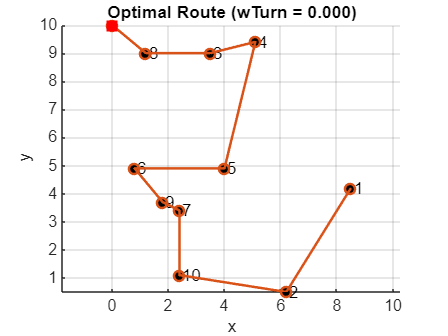

        Results for wTurn = 1.000


Best total cost : 32.3023


  Distance cost : 26.0803


  Turning cost  : 6.2220


Starting corner : (0.0, 10.0)


Visiting order  : 

8 3 4 5 6 9 7 10 2 1 

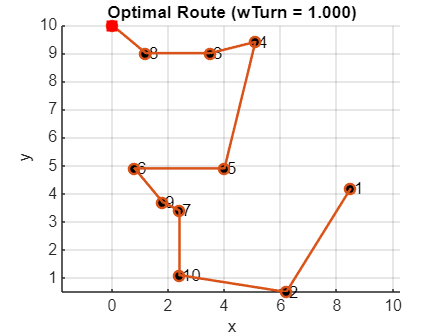

        Results for wTurn = 2.000


Best total cost : 36.9345


  Distance cost : 27.8926


  Turning cost  : 4.5209


Starting corner : (0.0, 0.0)


Visiting order  : 

10 2 1 5 7 9 6 8 3 4 

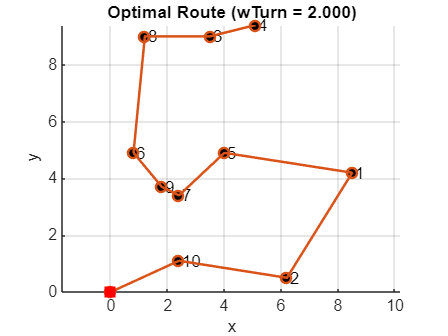

        Results for wTurn = 5.000


Best total cost : 49.5300


  Distance cost : 29.5514


  Turning cost  : 3.9957


Starting corner : (0.0, 0.0)


Visiting order  : 

10 2 1 4 3 8 6 9 7 5 

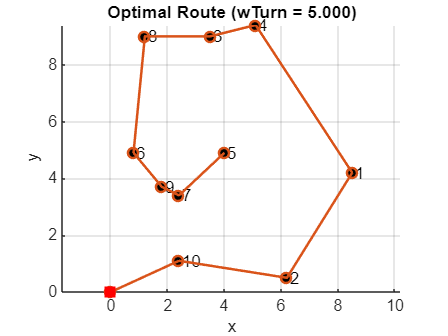

        Results for wTurn = 10.000


Best total cost : 69.5086


  Distance cost : 29.5514


  Turning cost  : 3.9957


Starting corner : (0.0, 0.0)


Visiting order  : 

10 2 1 4 3 8 6 9 7 5 

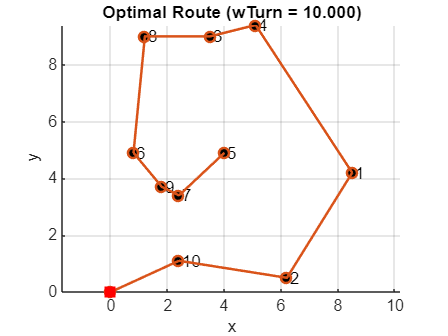

        Results for wTurn = 50.000


Best total cost : 226.2789


  Distance cost : 34.7860


  Turning cost  : 3.8299


Starting corner : (10.0, 10.0)


Visiting order  : 

5 7 9 6 8 3 4 1 2 10 

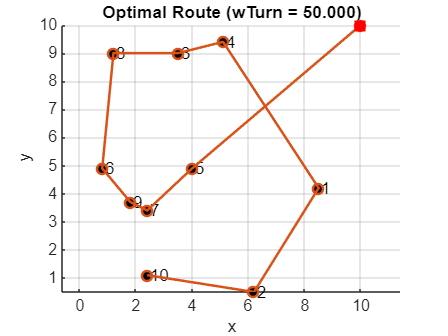

%% Shortest path through cities with turning penalty, sweeping wTurn
clear; clc; close all;

% City coordinates (rows = city 1..10)
cities = [ 8.5  4.2;
           6.2  0.5;
           3.5  9.0;
           5.1  9.4;
           4.0  4.9;
           0.8  4.9;
           2.4  3.4;
           1.2  9.0;
           1.8  3.7;
           2.4  1.1];

% Starting corners
startCorners = [0  0;
                0 10;
               10  0;
               10 10];

nCities = size(cities,1);
cityIdx = 1:nCities;

% Precompute all possible city visitation orders
allPerms = perms(cityIdx);
nPerms   = size(allPerms,1);

% Weights to sweep
wTurnList = [0, 1, 2, 5, 10, 50];

%% LOOP THROUGH WEIGHTS
for wIndex = 1:length(wTurnList)
    wTurn = wTurnList(wIndex);

    bestCost = inf;
    bestOrder = [];
    bestStart = [];
    bestDist = [];
    bestTurnCost = [];

    % ============================================================
    % Search for optimal path for this wTurn
    % ============================================================
    for k = 1:nPerms
        order = allPerms(k,:);
        routeCities = cities(order,:);

        for sc = 1:size(startCorners,1)
            start = startCorners(sc,:);
            route = [start; routeCities];

            % ---- Distance cost ----
            segs     = diff(route,1,1);
            segLens  = sqrt(sum(segs.^2,2));
            distCost = sum(segLens);

            % ---- Turning cost ----
            turnCost = 0;
            for i = 2:(size(route,1)-1)
                v1 = route(i,:)   - route(i-1,:);
                v2 = route(i+1,:) - route(i,:);
                n1 = norm(v1); 
                n2 = norm(v2);
                if n1 > 0 && n2 > 0
                    cosTheta = dot(v1,v2)/(n1*n2);
                    cosTheta = max(min(cosTheta,1),-1);
                    turnCost = turnCost + (1 - cosTheta);
                end
            end

            % ---- Combined cost ----
            totalCost = distCost + wTurn * turnCost;

            if totalCost < bestCost
                bestCost     = totalCost;
                bestOrder    = order;
                bestStart    = start;
                bestDist     = distCost;
                bestTurnCost = turnCost;
            end
        end
    end

    % ============================================================
    % Print results for this weight
    % ============================================================
    fprintf("\n=============================================\n");
    fprintf("        Results for wTurn = %.3f\n", wTurn);
    fprintf("=============================================\n");
    fprintf("Best total cost : %.4f\n", bestCost);
    fprintf("  Distance cost : %.4f\n", bestDist);
    fprintf("  Turning cost  : %.4f\n", bestTurnCost);
    fprintf("Starting corner : (%.1f, %.1f)\n", bestStart(1), bestStart(2));
    fprintf("Visiting order  : ");
    fprintf("%d ", bestOrder);
    fprintf("\n");

    % ============================================================
    % Plot the best route for this wTurn
    % ============================================================
    figure;
    hold on; grid on; axis equal;

    % Plot cities
    plot(cities(:,1), cities(:,2), 'ko', 'MarkerFaceColor','k');
    for i = 1:nCities
        text(cities(i,1)+0.1, cities(i,2), sprintf('%d', i));
    end

    % Plot route
    routePlot = [bestStart; cities(bestOrder,:)];
    plot(routePlot(:,1), routePlot(:,2), '-o', 'LineWidth', 1.5);

    % Highlight starting corner
    plot(bestStart(1), bestStart(2), 'rs', 'MarkerFaceColor','r', 'MarkerSize', 8);

    title(sprintf('Optimal Route (wTurn = %.3f)', wTurn));
    xlabel('x'); ylabel('y');
end